figure()
load("encoder_data_2.mat")
for row = 1:length(encoder_data) - 14
    if encoder_data(row, 1) == 0
        encoder_data(row, :) = [];
    end
end
encoder_data = encoder_data(1:10, :)

encoder_data =     6.9366    0.6610   -0.6520
   30.2268    2.9970    1.6090
   36.2018    2.4820    2.2250
   38.0013    2.5540    2.3830
   38.3189    2.5950    2.4270
   47.3978    3.4120    3.3320
   49.3144    3.5930    3.2300
   55.3587    4.2150    3.7230
   55.5182    4.2340    3.7400
   60.8862    4.7090    4.2740


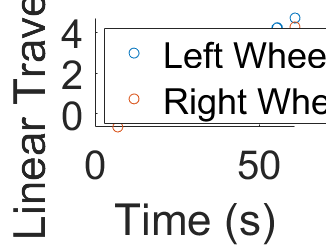

scatter(encoder_data(:,1),encoder_data(:,2:3));
set(gca,'FontSize',24);
xlabel("Time (s)")
ylabel("Linear Travel (m)")
legend('Left Wheel','Right Wheel','Location','northwest');

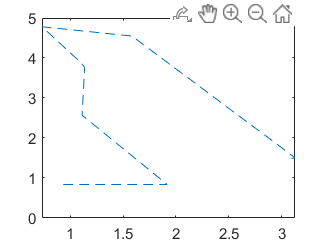


encoder_diff = diff(encoder_data);
speeds = [encoder_diff(:,2)./encoder_diff(:,1), encoder_diff(:,3)./encoder_diff(:,1)];
left_new = [];
time_old = encoder_data(:,1);
time_new_left = [];
right_new = [];
time_new_right = [];

count = 1;
for i=1:length(speeds)
    if speeds(i,1) ~= 0 && speeds(i,1) <= 0.3 
        left_new(count,1) = speeds(i,1);
        time_new_left(count,1) = time_old(i);
        count = count + 1;
    end
end
count = 1;
for i=1:length(speeds)
    if speeds(i,2) ~= 0 && speeds(i,2) <= 0.3
        right_new(count,1) = speeds(i,2);
        time_new_right(count,1) = time_old(i);
        count = count + 1;
    end
end

ang_speed = ((speeds(:,2)-speeds(:,1))./0.245);
ang_speed_new = [];
time_old = encoder_data(:,1);
time_new = [];
count = 1;
for i=1:length(ang_speed)
    if ang_speed(i) ~= 0 
        ang_speed_new(count,1) = ang_speed(i);
        time_new(count,1) = time_old(i);
        count = count + 1;
    end
end

big_V = (sum(speeds, 2))/2;
big_V_current = big_V(1);
x_pos = 0.933;
y_pos = 0.838;
x_pos_list = [x_pos];
y_pos_list = [y_pos];
theta = 0;
for i = 2:length(time_old)-1
    big_V_current = big_V(i);
    delta_t = time_old(i) - time_old(i-1);
    delta_t = delta_t/0.2;
    x_pos = x_pos + big_V_current*cos(theta)*delta_t;
    y_pos = y_pos + big_V_current*sin(theta)*delta_t;
    theta = theta + ang_speed(i)*delta_t;
    x_pos_list(i, 1) = x_pos;
    y_pos_list(i,1) = y_pos;
end

figure()
plot(x_pos_list, y_pos_list, "--")